# **Interoperability**

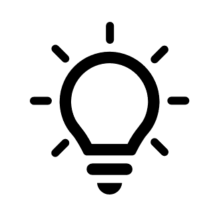 Where do I find MATLAB? [Here](https://www.mathworks.com/academia/tah-portal/wits-university-40783970.html)!

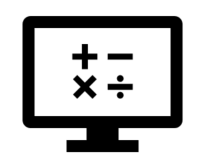 Do I have to have MATLAB installed on my computer right now? No, you can use  [MALAB Online](https://matlab.mathworks.com/)!

## Recap of Week 6, Part 1: Big Picture 

This week in part 1, we learnt about: 

- What is computational thinking?

- Why is computational thinking important? 

- How do we become computational thinkers? 

In the next part of this week's content, we will be learning about interoperability, covering the following sub-topics: 

- Interoperability with other languages

- MATLAB and Python 

## MATLAB Interoperability with other languages

Interoperability is the ability of computer systems or software to exchange and make use of information. MATLAB offers interoperability between many other languages, as well as three means of achieving this: 

- Call libraries written in another language from MATLAB 

- Call MATLAB from another language 

- Package MATLAB programs as software components for use in other languages

The following graphic covers each of these in more details, but we encourage you to consult [this link](https://www.mathworks.com/products/matlab/matlab-and-other-programming-languages.html) for more information on using MATLAB with other languages. 

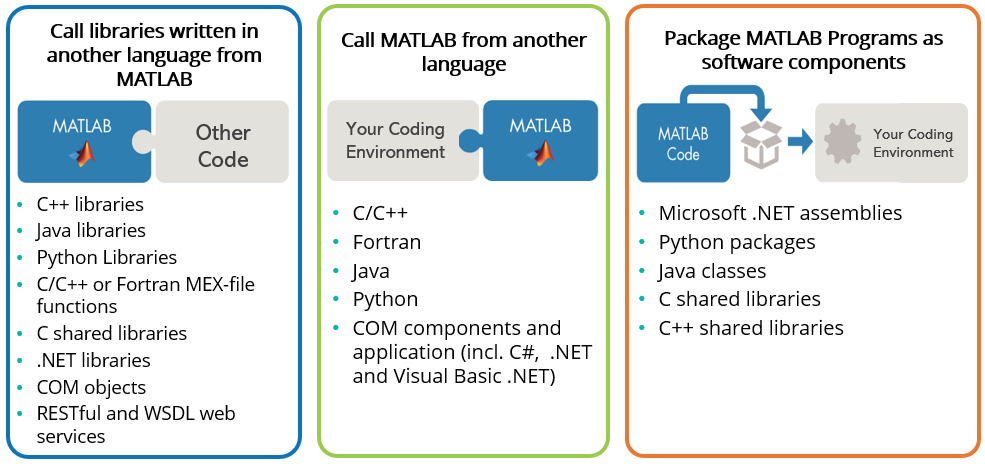

You can also leverage open architecture formats in your workflow. The ONNX model format is one such example, where importing and exporting of Deep Learning models in MATLAB (and consequently Simulink) enables cross-tool development, testing, and deployment. See the [Deep Learninig Import and Export](https://www.mathworks.com/help/deeplearning/deep-learning-import-and-export.html) documentation for more information on this. 

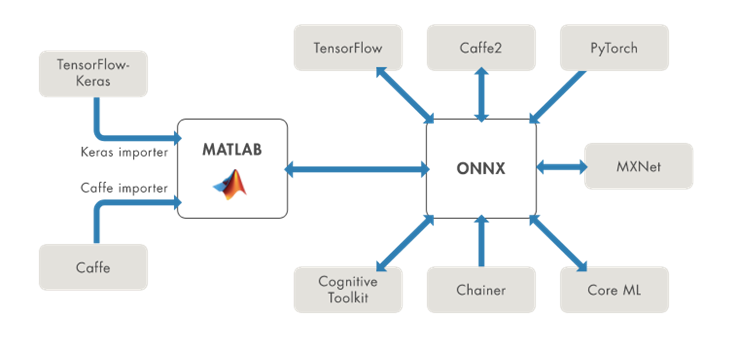

### MATLAB and Python 

For the remainder of this section, we will be covering a basic call of Python from the MATLAB environment. If you already have Python installed, be sure to check if the version interfaces with MATLAB by consulting [this link](https://www.mathworks.com/support/requirements/language-interfaces.html). For Python installation support, please consult the [Configure Your System to Use Python](https://www.mathworks.com/help/matlab/matlab_external/install-supported-python-implementation.html) documentation. Be sure install a version that can interface with MATLAB. 

**Note:** You can always use MATLAB Online for working with Python in MATLAB. This environment has already been configured for your ease of access. 

Assuming you are all setup and ready to move forward, let us do a quick check with MATLAB what version of Python is recognising. We use the command `pyenv` (or `pyversion` if you are using a MATLAB version prior to R2019b). 

pyenv

The output from this command will supply you with the version of Python being recognised, for example `3.9`. If you receive an empty string response for the Version, MATLAB is not recognising your Python installation and you should check that a compatible version is installed correctly. You may need to [Install MATLAB Engine API for Python](https://www.mathworks.com/help/matlab/matlab_external/install-the-matlab-engine-for-python.html).

**Use Python Numeric Types in MATLAB**

When calling a Python function that takes a numeric input argument, MATLAB converts double values into types that best represent the data to the Python language. For example, to call trigonometry functions in the Python `math` module, pass a MATLAB double value.

pynum = py.math.radians(90)

pynum =    1.570796326794897

For functions that return Python `float` types, MATLAB automatically converts this type to double.

class(pynum)

ans = 'double'

For Python functions returning integer types, MATLAB automatically converts this type to `int64`. For example, the `bit_length` function returns the number of bits necessary to represent an integer in binary as an `int` value.

py.int(intmax).bit_length

ans =   Python int with properties:

    denominator: [1×1 py.int]
           imag: [1×1 py.int]
      numerator: [1×1 py.int]
           real: [1×1 py.int]
    31

Now you try! Create a row vector, `x`, with the value `2`, `4`, and `6`, and use `fsum` from the Python `math` module to determine its sum. 

x = 2:2:6;
py.math.fsum(x)

ans =     12

**More resources:**

For more information on how to call Python from MATLAB or MATLAB from Python, watch the following video tutorial: 

- [Video tutorial: How to Call Python from MATLAB](https://www.mathworks.com/videos/how-to-call-python-from-matlab-1571135771573.html)

- [Video tutorial: How to Call MATLAB from Python](https://www.mathworks.com/videos/how-to-call-matlab-from-python-1571136879916.html) 

You can also consult the [Cheat Sheets for Using MATLAB with Python](https://www.mathworks.com/campaigns/offers/matlab-python-cheat-sheets.html) for getting started.

## What we've covered this week in part 2: Interoperability

This week in part 2, we learnt about: 

- Interoperability with other languages

- MATLAB and Python 

In the next part of this week's content, we will be demonstrating Beyond Introduction to Programming, covering the following sub-topics: 

- Symbolic Math

- Object-Oriented Programming (OOP)

- Simulink

## Extra resources

- [Documentation: MATLAB Interfaces to Other Languages](https://www.mathworks.com/support/requirements/language-interfaces.html)

- [Video: Interoperability of MATLAB with other Programming Languages](https://www.mathworks.com/videos/interoperability-of-matlab-with-other-programming-languages-1623071387701.html#:~:text=MATLAB%20offers%20a%202%2Dway,from%20one%20environment%20to%20another.)

- [Cheat Sheets for Using MATLAB with Python](https://www.mathworks.com/campaigns/offers/matlab-python-cheat-sheets.html) 

- [Self-Paced Online Courses](https://matlabacademy.mathworks.com/)

## References

- [Using MATLAB with Other Programming Languages](https://www.mathworks.com/products/matlab/matlab-and-other-programming-languages.html)

- [Documentation: Use Python Numeric Variables in MATLAB](https://www.mathworks.com/help/matlab/matlab_external/pythonnumericvariables.html)

- [Video tutorial: How to Call Python from MATLAB](https://www.mathworks.com/videos/how-to-call-python-from-matlab-1571135771573.html)

- [Video tutorial: How to Call MATLAB from Python](https://www.mathworks.com/videos/how-to-call-matlab-from-python-1571136879916.html)

***Copyright 2022 The MathWorks, Inc. & Opti-Num Solutions (Pty) Ltd. ***